clear all
clc
syms x1(t) x2(t) y1(t) y2(t) theta1(t) theta2(t) F1x(t) F1y(t) F2x(t) F2y(t) F3x(t) F3y(t)

syms m1 m2 L g

IG1=1/12*m1*L^2; IG2=1/12*m2*L^2;

rG1=[x1(t);y1(t)];
rG2=[x2(t);y2(t)];
F1=[F1x(t);F1y(t)];
F2=[F2x(t);F2y(t)];
F3=[F3x(t);F3y(t)];

%Forces 1 and 2 act on the top arm, Force 3 on the bottom arm. 

%F=ma for top arm
eq1=m1*diff(rG1,t,t)==F1+F2-m1*g*[0;1];
MF1G1=cross(-[rG1;0],[F1;0]);
MF2G1=cross([rG1;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IG1*diff(theta1(t),t,t)==MF1G1(3)+MF2G1(3);

%F=ma for the bottom arm.
eq3=m2*diff(rG2,t,t)==F3-m2*g*[0;1];
%IG theta''=M for the bototm.
MF3G2=cross(L/2*[-sin(theta2(t));cos(theta2(t));0],[F3;0]);
eq4=IG2*diff(theta2(t),t,t)==MF3G2(3);

%Keep top arm anchored at origin. 
eq5=rG1+L/2*[-sin(theta1(t));cos(theta1(t))]==[0;0];
%Keep top arm and bottom arm attached. 
eq6=rG1+L/2*[sin(theta1(t));-cos(theta1(t))]==rG2+L/2*[-sin(theta2(t));cos(theta2(t))];
%F2 and F3 must be related. 
eq7=F2==-F3;

DES=[eq1;eq2;eq3;eq4;eq7];
disp_const=[eq5;eq6];
vel_const = [];



[DEs,PPs]=generateGoveringDEs(DES,disp_const,vel_const,[theta1,diff(theta1),theta2,diff(theta2)]);

The unknown functions are:
F1x(force)
F2x(force)
F3x(force)
F1y(force)
F2y(force)
F3y(force)
theta1
theta2
x1
x2
y1
y2

Expected Number of State Variables:4


%Check it out, you can use other functions as the state variables as well,
%though it starts to take a long time to solve. 

generateGoveringDEs(DES,disp_const,vel_const,[theta1,diff(theta1),x2,diff(y2)])

The unknown functions are:
F1x(force)
F2x(force)
F3x(force)
F1y(force)
F2y(force)
F3y(force)
theta1
theta2
x1
x2
y1
y2

Expected Number of State Variables:4
Warning! There are multiple branches for Dtheta1tt. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for Dx2tt. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for Dy2tt. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for Dtheta2t. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for Dtheta2tt. This likely means that this dyna

The unknown functions (just the base functions, not derivatives) are: theta1(t),theta2(t)


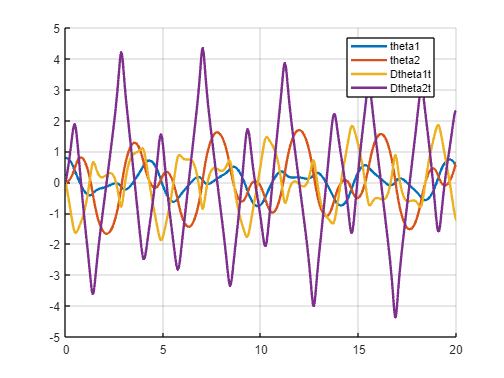

paramVals.m1=4; paramVals.m2=2; paramVals.L=3; paramVals.g=9.81;
specificDEs = subs(DEs,paramVals);
specificPPs = subs(PPs,paramVals);
soln=timeStepODESystem(specificDEs,[0,20],...
    [theta1==pi/4,theta2==0,diff(theta1)==0,diff(theta2)==0],specificPPs);

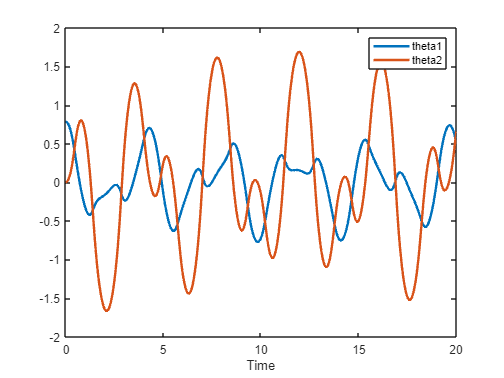


plot(soln.t,soln.theta1,soln.t,soln.theta2,'LineWidth',2); legend({'theta1','theta2'});xlabel('Time')

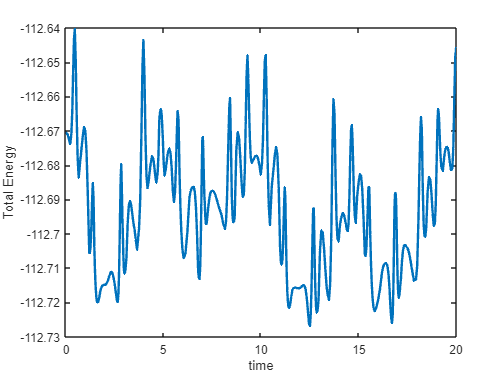

KineticEnergy=subs(1/2*m1*(soln.Dx1t.^2+soln.Dy1t.^2)+1/2*m2*(soln.Dx2t.^2+soln.Dy2t.^2)+...
    1/2*IG1*soln.Dtheta1t.^2+1/2*IG2*soln.Dtheta2t.^2,paramVals);
PotentialEnergy=subs(m1*soln.y1*g+m2*soln.y2*g,paramVals);
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')